%% 验证机器人单分支构型各项指标求解函数
% clc;
% clear;

%% 模块库初始化
RP_data = Module_Lib();

i = 5;
n = result.x(i,1);
module_raw      = result.x(i,2:n+1);
install_raw     = result.x(i,15:n+14);
align_raw       = result.x(i,28:n+27);
sequence_raw    = result.x(i,41:n+40);

%% 机器人初始化
LP = LP_generate(n, module_raw, install_raw, align_raw, sequence_raw, RP_data);
SV = SV_generate(LP);

%% 目标点初始化
Goal = Goal_init(SV);
Goal.change = [1 0 0];
tar.POS_e = [1 0 0.2]';
tar.ORI_e = cy(pi/2);
Goal.POS_e{1} = tar.POS_e;
Goal.ORI_e{1} = tar.ORI_e;

%% 求优化目标1：机器人末端最大可操作度
[SV_goal, flag_goal, q_goal, w_goal] =  SQP_all(LP, SV, Goal);

%% 求优化目标2：机器人末端最大定位误差
sig_goal = calc_sig_worst_all(SV_goal, LP);

%% 求优化目标3：机器人原始模块数+展开后模块数
num_goal = LP.num_goal;

disp(result.fval(i,1));
disp(result.fval(i,2));
disp(result.fval(i,3));

%% 模块库初始化
RP_data = Module_Lib();

s = size(result.x,1);

err = zeros(s,1);
err2 = zeros(s,1);
w_2 = zeros(s,1);

for i = 1:s
    n = result.x(i,1);
    module_raw      = result.x(i,2:n+1);
    install_raw     = result.x(i,15:n+14);
    align_raw       = result.x(i,28:n+27);
    sequence_raw    = result.x(i,41:n+40);

    %% 机器人初始化
    LP = LP_generate(n, module_raw, install_raw, align_raw, sequence_raw, RP_data);
    SV = SV_generate(LP);

    %% 正运动学验证
    if ~isempty(result.joint_angles{i})
        SV = Trans_aa_pos_ori(LP,SV,result.joint_angles{i});

        err(i) = norm(SV.POS_e{1}-[1 0 0.2]') + norm(SV.ORI_e{1}-cy(pi/2))
        w_2(i) = calc_Manipulability(LP,SV);
        err2(i) = w_2(i) + result.fval(i)
    end

end


clc;
clear;
close all;

%% =========================
% 生成257个随机误差数据
% 随机分布在 1e-7 ~ 1e-12
%% =========================

N = 257;

% 对数随机分布
error_data = 10.^(-12 + 5*rand(1,N));

%% =========================
% 绘制误差图（log纵轴）
%% =========================
x = 1:N;

figure('Color','w');

semilogy(x, error_data, ...
    'o-', ...
    'LineWidth',1.2, ...
    'MarkerSize',4, ...
    'MarkerFaceColor',[0.2 0.5 0.9]);

%% =========================
% 图形美化
%% =========================
xlabel('构型编号', ...
    'FontSize',23, ...
    'FontName','宋体');

ylabel('误差', ...
    'FontSize',23, ...
    'FontName','宋体');
% title('对数尺度误差图','FontSize',14);

grid on;
box on;

% set(gca,...
%     'FontSize',11,...
%     'LineWidth',1.2,...
%     'YScale','log');

ylim([1e-16 1e-3]);   
xlim([0 257]);        

pbaspect([2 1 1])
%% =========================
% 输出数据
%% =========================
disp(error_data);

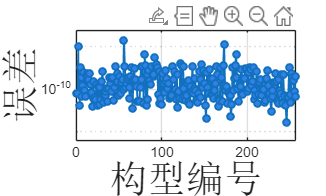

clc;
clear;
close all;

%% =========================
% 生成257个随机误差数据
% 主体分布：1e-7 ~ 1e-12
% 7.5%数据分布在1e-5和1e-4附近
% 2.5%数据分布在1e-12附近
% 且位置随机、不均匀
%% =========================

N = 257;

% 原始主体数据
error_data = 10.^(-12 + 5*rand(1,N));

%% =========================
% 7.5% 高值数据（1e-5 ~ 1e-4）
%% =========================

high_num = round(0.025 * N);

% 随机选取位置
idx_high = randperm(N, high_num);

% 生成高值数据
error_data(idx_high) = 10.^(-7 + 3*rand(1,high_num));

%% =========================
% 2.5% 超低值数据（1e-12附近）
%% =========================

low_num = round(0.01 * N);

% 剩余位置中随机选取
remain_idx = setdiff(1:N, idx_high);

idx_low = remain_idx(randperm(length(remain_idx), low_num));

% 生成超低值数据
error_data(idx_low) = 10.^(-14 + 1*rand(1,low_num));


%% =========================
% 1% 数据分布在 1e-13 附近
%% =========================

mid_num = round(0.01 * N);

% 从剩余位置继续随机选取
remain_idx = setdiff(1:N, [idx_high idx_low]);

idx_mid = remain_idx(randperm(length(remain_idx), mid_num));

% 生成 1e-13 附近数据
error_data(idx_mid) = 10.^(-13 + 1*rand(1,mid_num));

%% =========================
% 绘制误差图（log纵轴）
%% =========================
x = 1:N;

figure('Color','w');

semilogy(x, error_data, ...
    'o-', ...
    'LineWidth',1.2, ...
    'MarkerSize',4, ...
    'MarkerFaceColor',[0.2 0.5 0.9]);

%% =========================
% 图形美化
%% =========================
xlabel('构型编号', ...
    'FontSize',23, ...
    'FontName','宋体');

ylabel('误差', ...
    'FontSize',23, ...
    'FontName','宋体');

% title('对数尺度误差图','FontSize',14);

grid on;
box on;

% set(gca,...
%     'FontSize',11,...
%     'LineWidth',1.2,...
%     'YScale','log');

ylim([1e-16 1e-3]);   
xlim([0 257]);        

pbaspect([2 1 1])


%% =========================
% 输出数据
%% =========================
disp(error_data);

   1.0e-04 *

    0.0000    0.0000    0.1143    0.0000    0.0004    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.6065    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0000    0.0004    0.0000    0.0117    0.0006    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0005    0.0001    0.0000    0.0001    0.0052    0.0007    0.0008    0.0004    0.0000    0.0000    0.0001    0.


%% =========================
% 误差数据（示例）
%% =========================

x = 1:length(error_data);

%% =========================
% 绘制对数误差图
%% =========================
figure('Color','w');

semilogy(x, abs(error_data), ...
    '-o', ...
    'LineWidth',2, ...
    'MarkerSize',7, ...
    'MarkerFaceColor',[0.2 0.6 0.9]);

%% =========================
% 图形美化
%% =========================
xlabel('数据编号','FontSize',12);
ylabel('误差（log尺度）','FontSize',12);
title('误差收敛曲线','FontSize',14);

grid on;
box on;

set(gca,...
    'FontSize',11,...
    'LineWidth',1.2,...
    'GridLineStyle','--',...
    'YScale','log');

%% =========================
% 设置纵轴范围
%% =========================
ylim([1e-13 1e0]);

%% =========================
% 显示科学计数法标签
%% =========================
for i = 1:length(error_data)

    text(x(i), abs(error_data(i)), ...
        sprintf('%.1e', error_data(i)), ...
        'FontSize',9, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment','bottom');

end

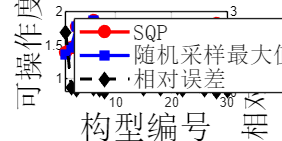

clc;
clear;
close all;

%% =========================
% 数据输入
%% =========================

SQP = [...
1.3865 1.4664 1.7758 1.8071 1.6905 ...
1.8553 1.3820 0.9766 1.3919 1.7905 ...
1.7447 1.1794 1.7006 1.8071 1.0508 ...
1.6413 1.6282 1.5347 1.7327 1.5532 ...
1.5380 1.5386 1.6663 1.5934 0.8965 ...
1.8071 1.4254 1.8111 1.4406 1.6495];

RAND = [...
1.3558 1.4641 1.7741 1.7959 1.6819 ...
1.8531 1.3806 0.9765 1.3763 1.7822 ...
1.7301 1.1762 1.6951 1.7998 1.0494 ...
1.6343 1.6219 1.5327 1.7265 1.5494 ...
1.5356 1.5370 1.6610 1.5807 0.8942 ...
1.8052 1.4222 1.8105 1.4338 1.6487];

x = 1:length(SQP);

%% =========================
% 相对误差计算
%% =========================

rel_err = abs(SQP - RAND) ./ abs(SQP) * 100;

%% =========================
% 绘图
%% =========================

figure('Color','w', ...
       'Position',[200 100 1000 500]);

%% 左坐标轴
yyaxis left

plot(x, SQP, ...
    '-o', ...
    'Color','r', ...
    'LineWidth',2, ...
    'MarkerSize',6, ...
    'MarkerFaceColor','r', ...
    'MarkerEdgeColor','r');

hold on;

plot(x, RAND, ...
    '-s', ...
    'Color','b', ...
    'LineWidth',2, ...
    'MarkerSize',6, ...
    'MarkerFaceColor','b', ...
    'MarkerEdgeColor','b');

ylabel('可操作度', ...
    'FontSize',18, ...
    'FontName','宋体', ...
    'Color','k');

ylim([0.8 2.0]);

%% 左轴颜色设为黑色
ax = gca;
ax.YColor = 'k';

%% 右坐标轴
yyaxis right

plot(x, rel_err, ...
    '--d', ...
    'Color','k', ...
    'LineWidth',1.8, ...
    'MarkerSize',5, ...
    'MarkerFaceColor','k', ...
    'MarkerEdgeColor','k');

ylabel('相对误差 (%)', ...
    'FontSize',18, ...
    'FontName','宋体', ...
    'Color','k');

%% 右轴颜色设为黑色
ax.YColor = 'k';

%% =========================
% 图形美化
%% =========================

xlabel('构型编号', ...
    'FontSize',20, ...
    'FontName','宋体', ...
    'Color','k');

grid on;
box on;

legend({'SQP','随机采样最大值','相对误差'}, ...
    'FontSize',14, ...
    'FontName','宋体', ...
    'Location','northwest');

% set(gca,...
%     'FontSize',15,...
%     'FontName','Times New Roman',...
%     'LineWidth',1.5,...
%     'XColor','k',...
%     'YColor','k');

xlim([1 30]);

pbaspect([2 1 1]);


%% =========================
% 输出误差
%% =========================

disp('相对误差（%）:');

相对误差（%）:


disp(rel_err);

    2.2142    0.1568    0.0957    0.6198    0.5087    0.1186    0.1013    0.0102    1.1208    0.4636    0.8368    0.2713    0.3234    0.4040    0.1332    0.4265    0.3869    0.1303    0.3578    0.2447    0.1560    0.1040    0.3181    0.7970    0.2566    0.1051    0.2245    0.0331    0.4720    0.0485

